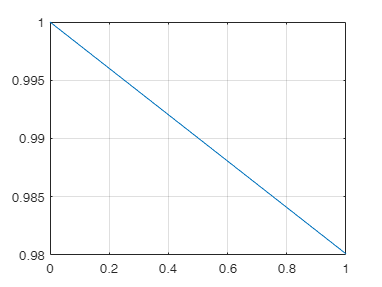

delta_f=10;

fs=300; 

nCyl = 5;

% t=0:1/fs:nCyl*1/f;
t=0:1;

x=(1-(t/delta_f).^2).^2;

plot(t,x);
grid("on");

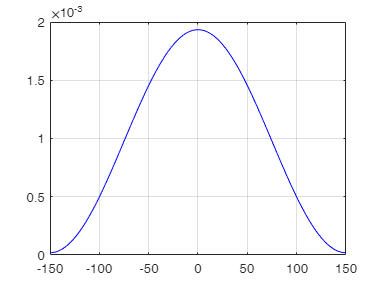


NFFT=1024;  
 
X=fftshift(ifft(x,NFFT));       

fVals=fs*(-NFFT/2:NFFT/2-1)/NFFT;   
 
plot(fVals,real(X),'b'); 
grid();